%Parameters

use_sync = 1;
rec_duration = 3600;                                                                            %approx rec duration (s)
ntw_time = 15.65e-12;                                                                           %network tic interval (s)
n_tags = 5;
TTL_time_diff = [21; 13; 8; 5; 4];                                                              %TTL delays in s
CDPmtdata.Fs = 100;    

data = load('extracted_210222_cdp_1.mat');

for i = 1:1
    tag_i = data.tag_data{i};
    bat_pos = tag_i(:,3:4);
    disp(size(bat_pos));
    
    bat_acc = data.tag_ac_data{i}(:, 3:4);
    disp(size(bat_acc));
    
    tag_filt = kalman_filter(bat_pos, bat_acc, 1/CDPmtdata.Fs);
    
end

      359746           2



      358049           2



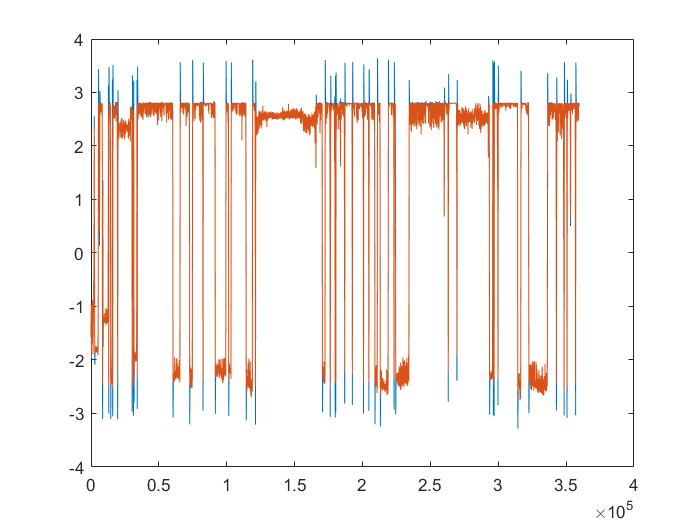

samples = linspace(1,length(bat_pos),length(bat_pos));
plot(samples, tag_filt(1,:), samples, bat_pos(:, 1))

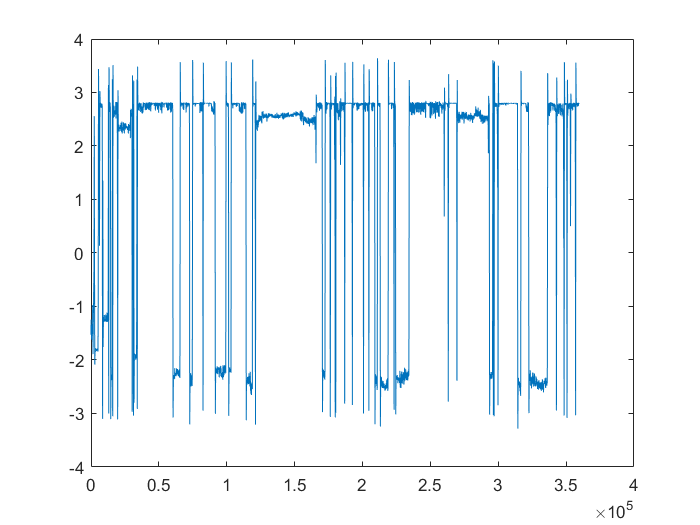

plot(tag_filt(1,:))

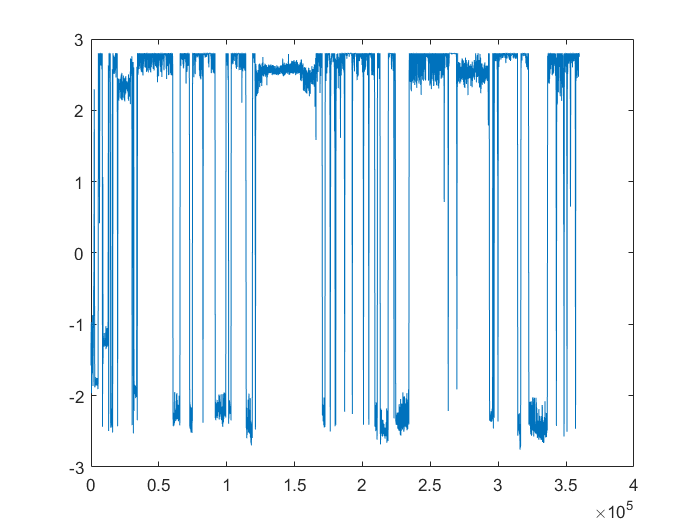

plot(bat_pos(:,1))

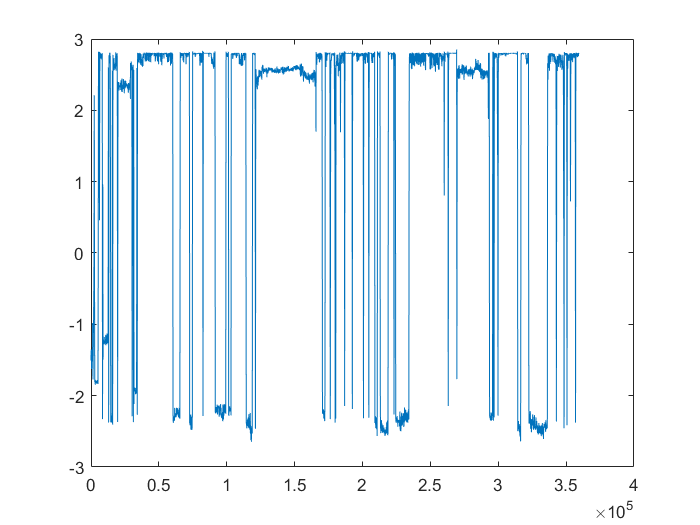

plot(data.tag_data_filt{1}(:, 3))